`In the name of God`

# Blind Source Separation

# Assignment #1

**Maryam Riazi**

**810197518**

### Introduction

    we create two sources as random processes with normal distribution. after we mix the sources with A (mixture matrix) and finally observe x1 and x2 as our observations. 

sz = [1,1000];

s1 = unifrnd(-3,3,sz);
s2 = unifrnd(-2,2,sz);

A = [0.6,0.8 ; 0.8 -0.6];
S = [s1;s2];

X = A*S;
x1 = X(1,:);
x2 = X(2,:);

### Question1. 

In this part we plot x1 and x2 with an scatter plot function. 

    There is 2 important information in this problem. First our mixture matrix which is declared as$\left\lbrack \begin{array}{cc}
0\ldotp 6 & 0\ldotp 8\\
0\ldotp 8 & -0\ldotp 6
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\textrm{a1} & \textrm{a2}
\end{array}\right\rbrack$ and second, the interval of our data which in s1 is [-3,3] and in s2 is [-2,2]. 

These two information would let us know that the borders of our scatter should be a1 and a2 and also the maximum and minimum of x1 and x2 would be drieved. 

For example, Max of x1 should be $0\ldotp 6*3+0\ldotp 8*2=3\ldotp 4$  

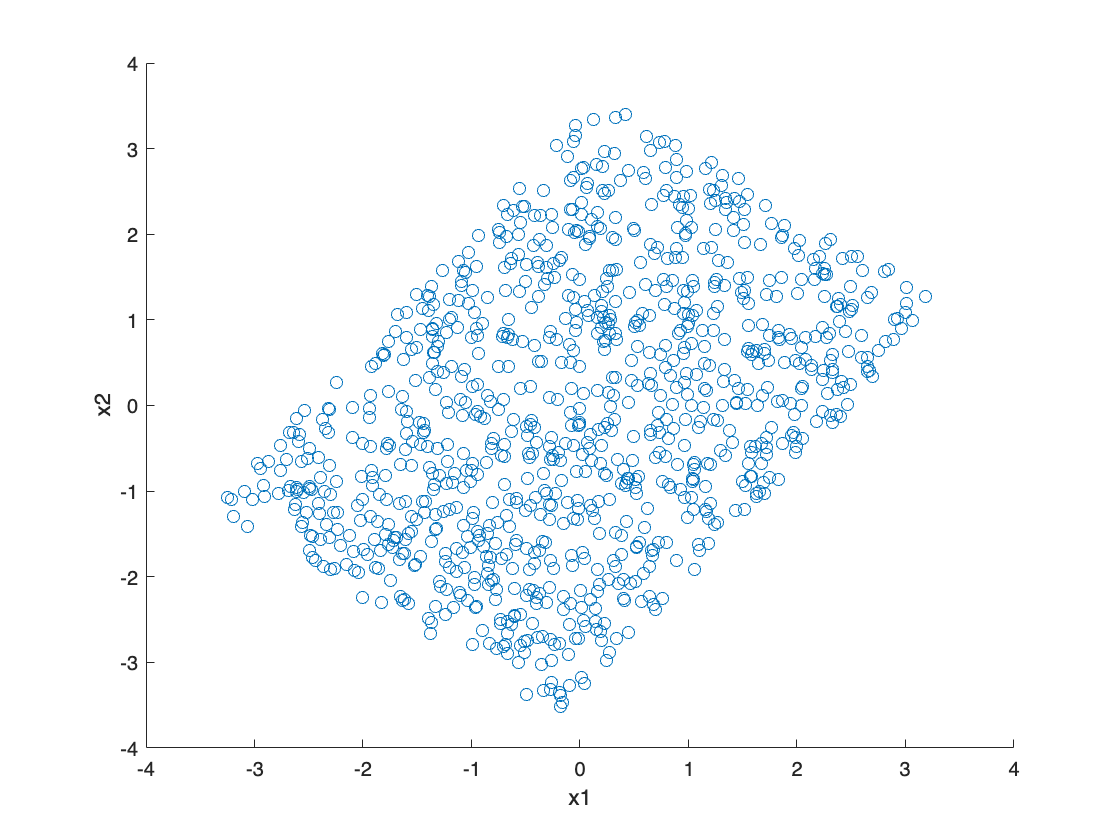

scatter(x1,x2);

xlabel('x1')
ylabel('x2')

### Question2.

My method in this question (finding mixture matrix A) is as below:

1) Find the index of the lowest x1. (first point of both border vectors)

2) Find the index of lowest and highest x2. (the second points for each border vector)

3) Find the lines of the vectors and normalize them. (Because |A| should be between 0 and 1)

There is also another method which would be more complicated. This method would be useful for a problem with more than two sources in which the scatter plot would be more complicated to be interpreted. In this method first we should find the border observations and then fit a line to them by regression methods.

[~,i1] = min(x1);
[~,i2] = min(x2);
[~,i3] = max(x2);
m1 = X(:,i1)';
m2 = X(:,i2)';
m3 = X(:,i3)';
a2 = (m2-m1)/norm(m2-m1);
a1 = (m3-m1)/norm(m3-m1);
B = [a1' a2']

B =     0.6339    0.7825
    0.7734   -0.6226


It is shown that our estimation (B) of A is so similar to A = $\left\lbrack \begin{array}{cc}
0\ldotp 6 & 0\ldotp 8\\
0\ldotp 8 & -0\ldotp 6
\end{array}\right\rbrack$

### Question3&4.

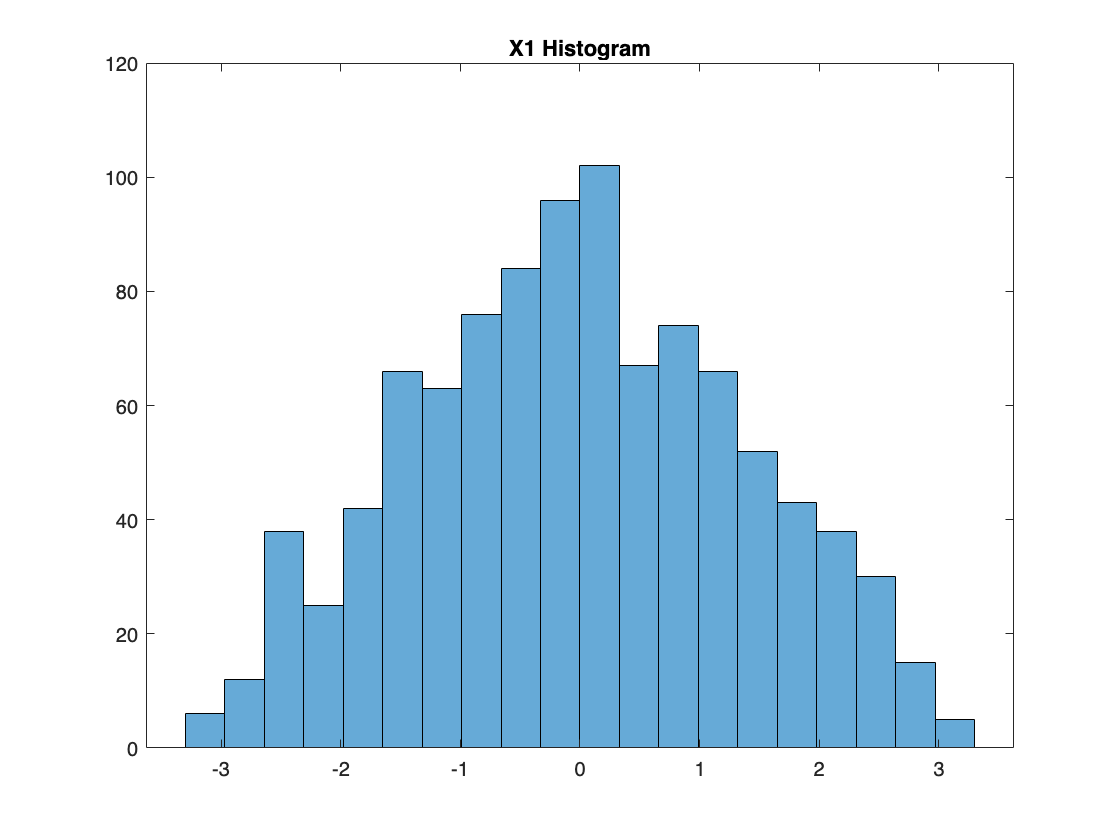

histogram(x1, 20)
title('X1 Histogram')

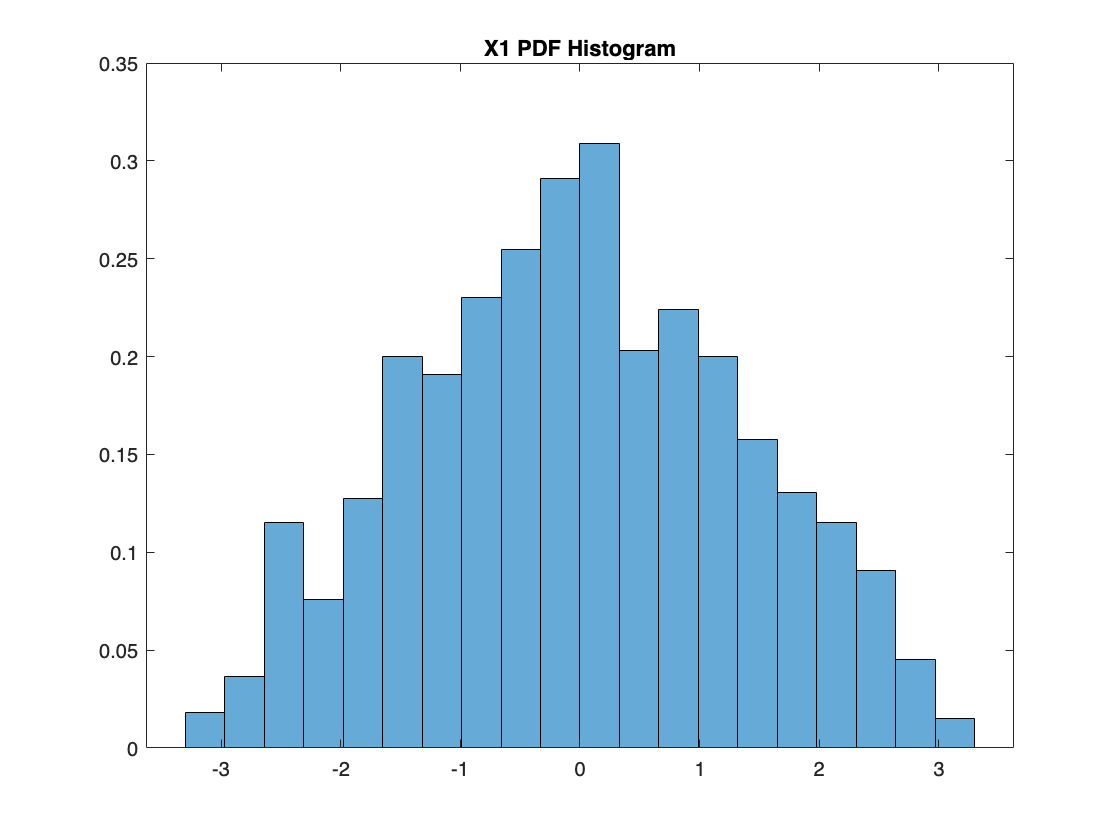

histogram(x1, 20, 'normalization', 'pdf')
title('X1 PDF Histogram')

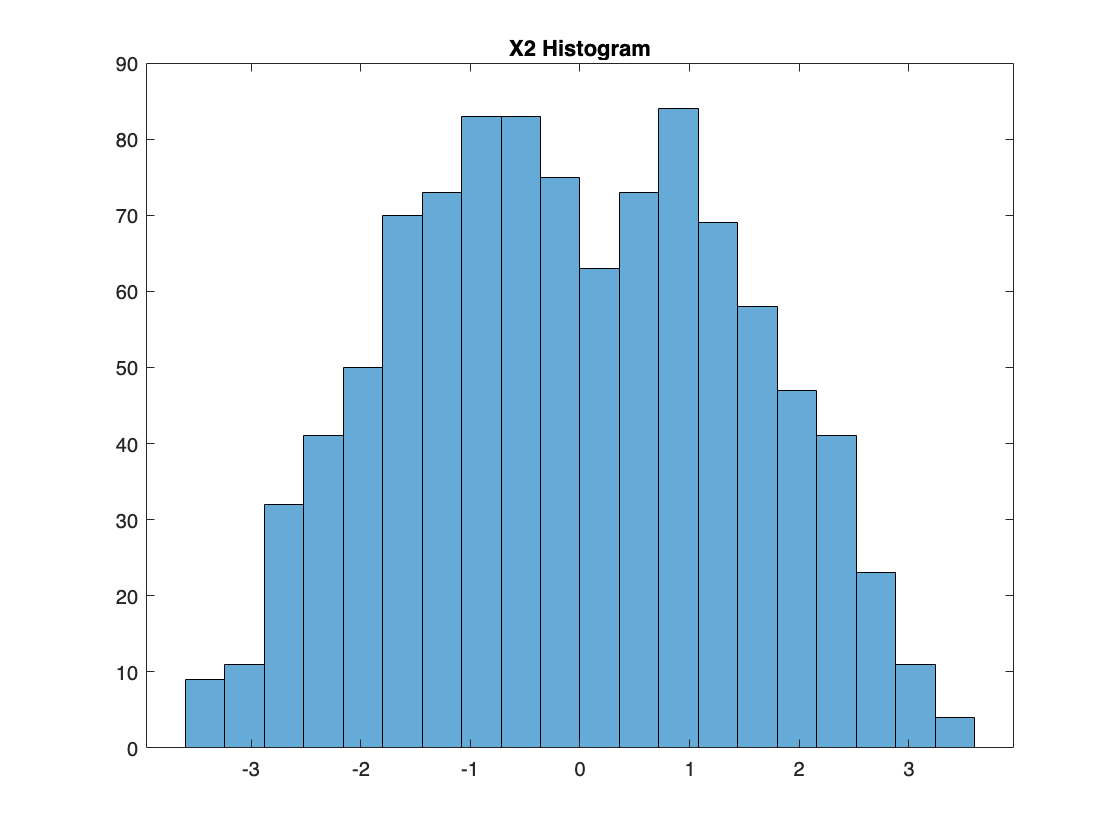


histogram(x2,20)
title('X2 Histogram')

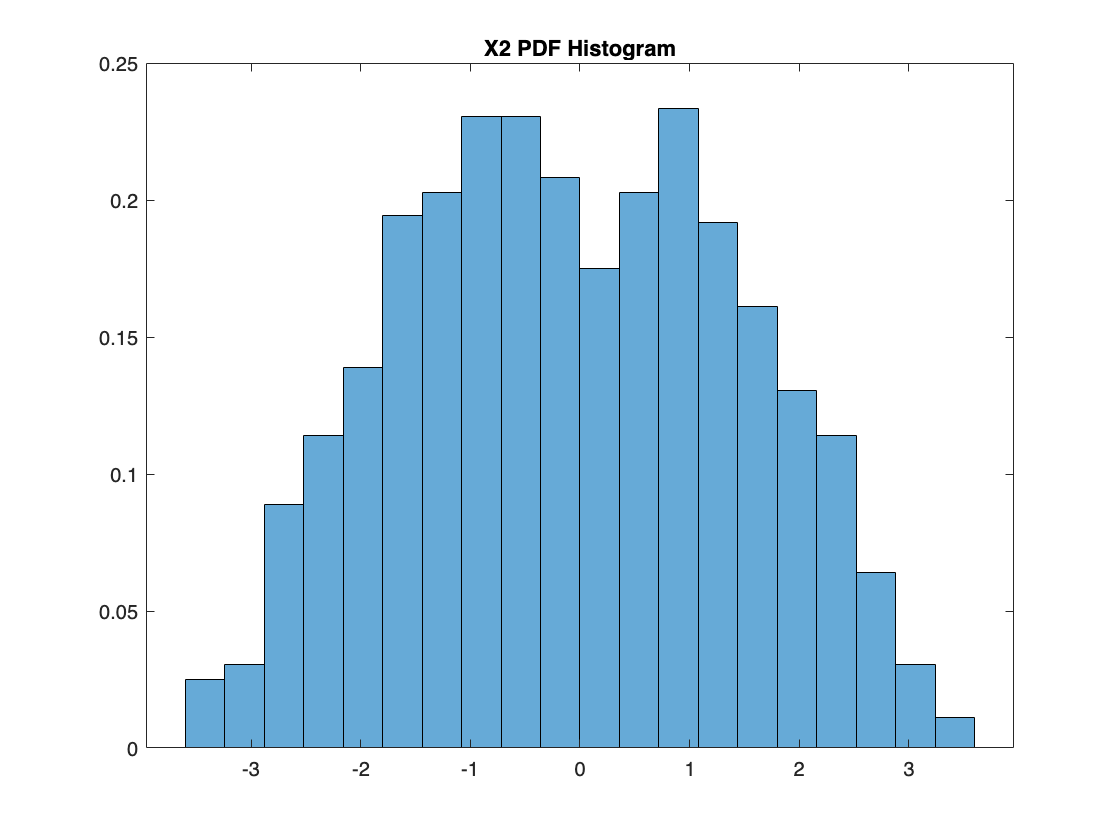

histogram(x2, 20, 'normalization', 'pdf')
title('X2 PDF Histogram')

Here is my solution to calculate the PDF of X1 and X2:

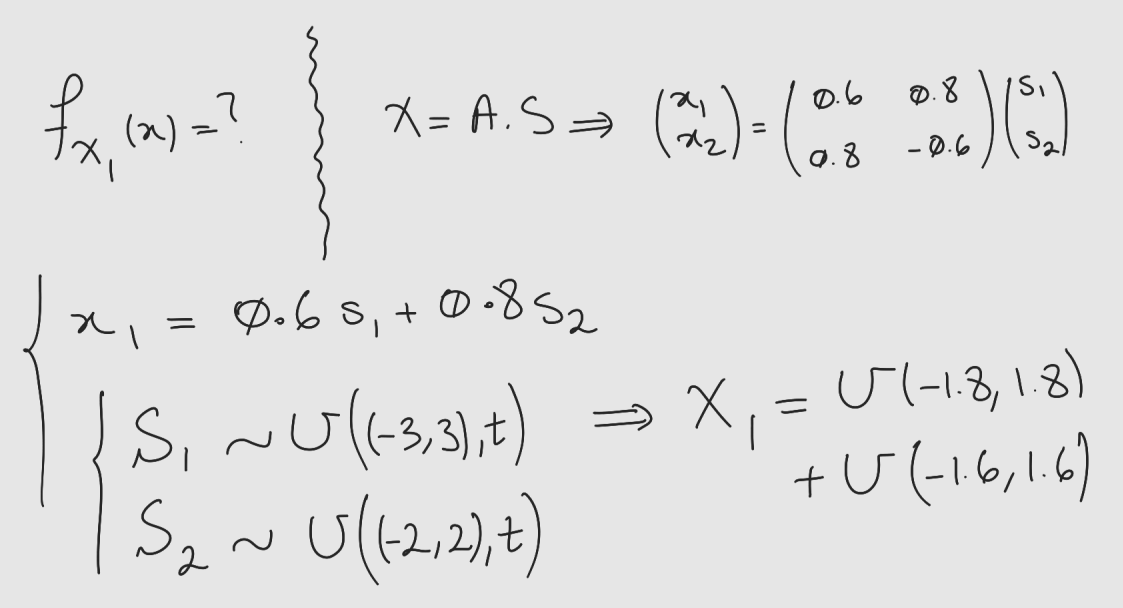

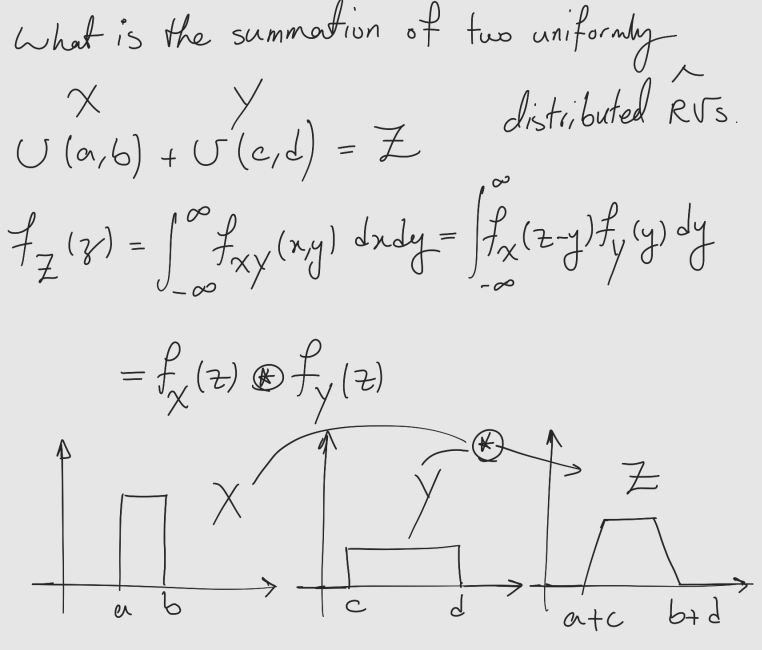

According to above explaination, PDF for X1 would be as below:

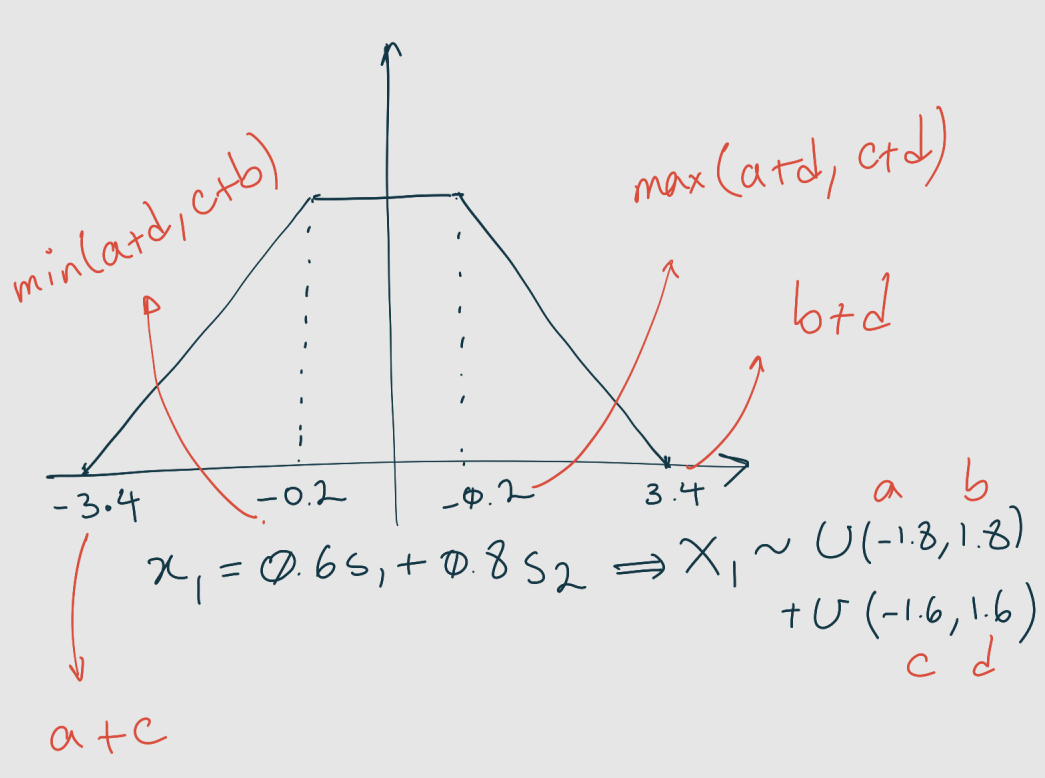

Similarly for X2, PDF would be as below:

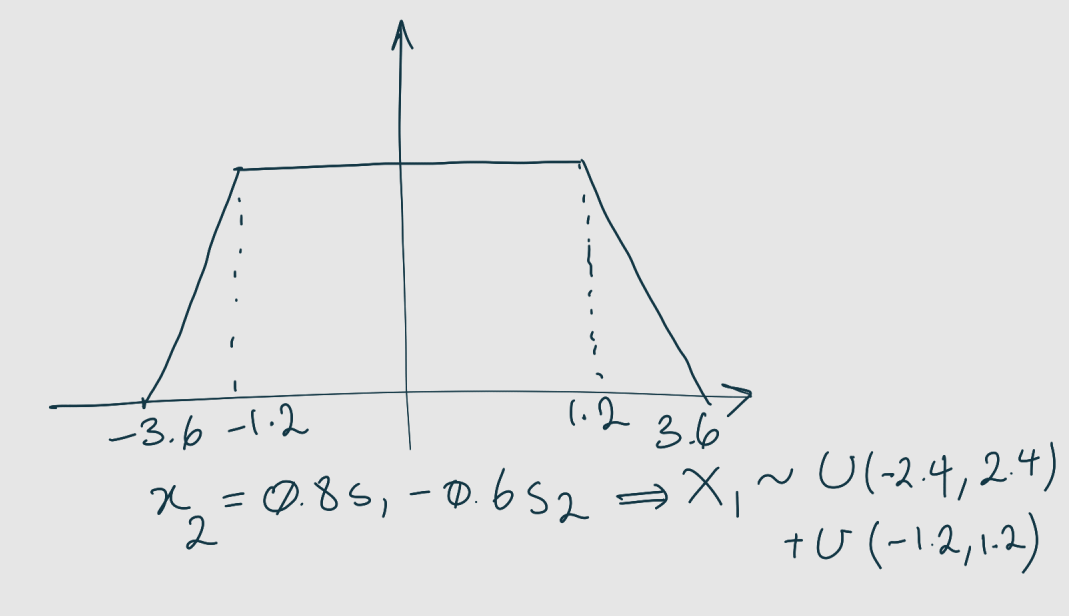

### Question5.

What do we have?

    1) PDF of the sources

    2) Numerical Interval of the sources

    3) Observations: X1 and X2

Mathematically, in this situation all we have is X1 and X2 (Observations) as below: 


$$\left\lbrace \begin{array}{cc}
X_1 ~a_{11} \times U\left\lbrack -3,3\right\rbrack +a_{12} \times U\left\lbrack -2,2\right\rbrack ~U\left\lbrack -1\ldotp 8,1\ldotp 8\right\rbrack +U\left\lbrack -1\ldotp 6,1\ldotp 6\right\rbrack =\textrm{convolution}\;\textrm{of}\;\textrm{both}\;U^{\prime } s & \;\\
X_2 ~a_{21} \times U\left\lbrack -3,3\right\rbrack +a_{22} \times U\left\lbrack -2,2\right\rbrack ~U\left\lbrack -2\ldotp 4,2\ldotp 4\right\rbrack +U\left\lbrack -1\ldotp 2,1\ldotp 2\right\rbrack =\textrm{convolution}\;\textrm{of}\;\textrm{both}\;U^{\prime } s & \;
\end{array}\right.$$


But here we have big problem! Convolution has commutativity property which in this case bother us to find the mixture matrix uniquely.

For example consider below in which we have two different mixture matrices but same PDF in our observations:


$$\left\lbrace \begin{array}{cc}
a_{11} \times U\left\lbrack -3,3\right\rbrack =U\left\lbrack -1\ldotp 8,1\ldotp 8\right\rbrack  & \;\\
a_{12} \times U\left\lbrack -2,2\right\rbrack =U\left\lbrack -1\ldotp 6,1\ldotp 6\right\rbrack  & \;
\end{array}\Rightarrow A=\left\lbrack \begin{array}{cc}
a_1  & a_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 6 & 0\ldotp 8\\
0\ldotp 8 & -0\ldotp 6
\end{array}\right\rbrack \right.$$



$$\left\lbrace \begin{array}{cc}
a_{11} \times U\left\lbrack -3,3\right\rbrack =U\left\lbrack -1\ldotp 6,1\ldotp 6\right\rbrack  & \;\\
a_{12} \times U\left\lbrack -2,2\right\rbrack =U\left\lbrack -1\ldotp 8,1\ldotp 8\right\rbrack  & \;
\end{array}\Rightarrow A=\left\lbrack \begin{array}{cc}
a_1  & a_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1\ldotp 6}{3} & 0\ldotp 9\\
0\ldotp 8 & -0\ldotp 6
\end{array}\right\rbrack \right.$$


Note that in this part, I do not consider X2 even and what I did was finding a11 and a12 in a way which X1 has two same PDFs.

In conclusion in this question we could not find A uniquely only by the question's assumptions. If we want to get A uniquely (with no attention to Scaling ambiguity and Order permutation), we should have the scatter plot of X1 over X2.